%%%%%%%%%%%%%%%%%%%%%%
%%%for turning netcdf files from Yongtao to wdr and wsp
%  intended to be run on PACE
%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%
%%%import & process data
%%%%%%%%%%%%%%%%%%%%%%

%%find current working folder
fp = "/storage/coda1/p-ar70/0/emei3/met-for-eto";

cd(fp) %%change to code folder
cd HIRES %need to change to data folder for netcdf to work

%%inputs
indsNeeded = 2:25; %hours needed to be indexed
%cell numbers, XY
all_xy = [31, 87; %STER
    29, 89; %MGE
    28, 83; %SSG
    30, 85; %FTY
    46, 83; %COV
    46, 83; %CVC
    38, 83]; %SDK

files = dir(strcat(fp, "/HIRES"));
fnames = {files.name}; %get file names
fnames([1, 2]) = []; %delete ".", ".."

%%pre-allocate tables
siteNames = ["STER", "MGE", "SSG", "FTY", "COV", "CVC", "SDK"];
allSiteData = struct(); %pre-allocate structure
for i = 1:length(siteNames) %pre-allocate all tables in structure
    siteName = siteNames(i);
    allSiteData.(siteName) = table();
end

for i = 1:length(fnames)
    fn = fnames{i}; %grab file name
    
    %%grab data
    %time
    time = ncread(fn, "TFLAG"); 
    day = squeeze(time(1, 1, :)); %extract dates
    hour = squeeze(time(2, 1, :)); %extract times
    temp = strcat(num2str(day), num2str(hour, "%06.f"));
    time = datetime(temp, "InputFormat", "uuuuDDDHHmmss", "TimeZone", "UTC");
    time.TimeZone = 'America/New_York'; %UTC to EST
    WDIR = ncread(fn, "WDIR10"); %degree
    WSPD = ncread(fn, "WSPD10"); %m/s

    for j = 1:length(siteNames) %pre-allocate all tables in structure
        siteName = siteNames(j); %grab current site
        xy = all_xy(j, :); %grab current site xy
        
        %%pre-table data
        tempData = table(time(indsNeeded), ...
            squeeze(WDIR(xy(1), xy(2), :, indsNeeded)), ...
            squeeze(WSPD(xy(1), xy(2), :, indsNeeded)));
        
        %%put data into table
        allSiteData.(siteName) = [allSiteData.(siteName); tempData];
    end

    %%4/28/2021 data missing (20210427 netcdf file), so use 0426 data
    %%instead
    if strcmp(fn, "METCRO2D_forecast4_20210426")
        tempIndsNeeded = 26:49; %grab later data from the file
        
        %copy earlier code but for different time range
        for j = 1:length(siteNames) %pre-allocate all tables in structure
            siteName = siteNames(j); %grab current site
            xy = all_xy(j, :); %grab current site xy

            %%pre-table data
            tempData = table(time(indsNeeded), ...
                squeeze(WDIR(xy(1), xy(2), :, indsNeeded)), ...
                squeeze(WSPD(xy(1), xy(2), :, indsNeeded)));

            %%put data into table
            allSiteData.(siteName) = [allSiteData.(siteName); tempData];
        end
    end
end

%%post-processing
varnames = ["time", "WDR", "WSP"]; %for column names
cd .. %for writing into file
for i = 1:length(siteNames) 
    siteName = siteNames(i);
    
    %%name columns
    allSiteData.(siteName).Properties.VariableNames = varnames;

    %%sort by time
    allSiteData.(siteName) = sortrows(allSiteData.(siteName), 1);

    %%write data into table
    writetable(allSiteData.(siteName), "WRF wind data 12-12.xlsx", ...
        "Sheet", siteName)
end

size(unique(STERdata.time))

ans =        26904           1


size(unique(SSGdata.time))

ans =        26904           1


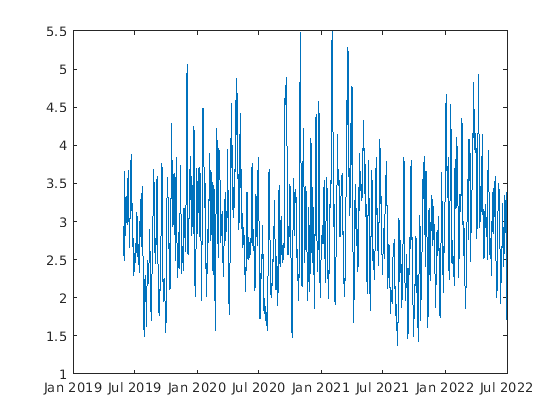

plot(STERdata.time, smooth(STERdata.WSP, 100))